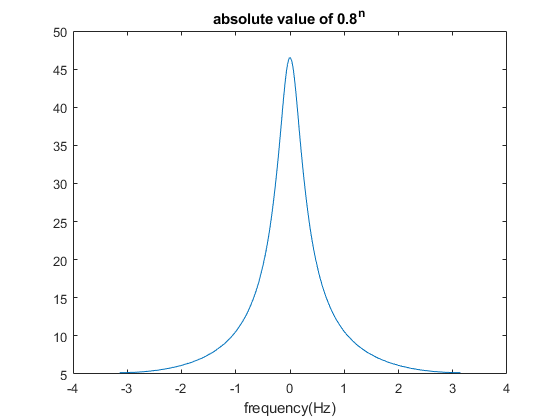


n = -10:20;
x1 = (0.8).^n;
s = -pi:pi/200:pi;
y1 = DTFT(x1,n);
plot(s,abs(y1))
title("absolute value of 0.8^n")
xlabel("frequency(Hz)")

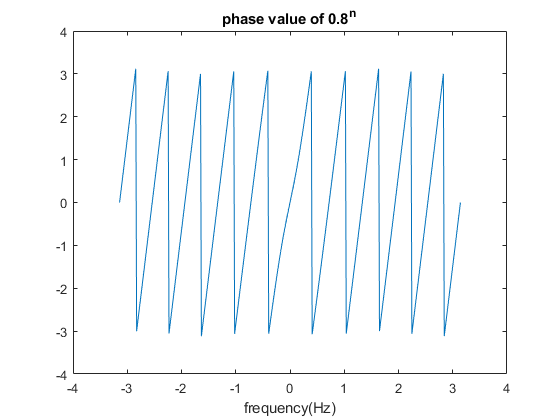


plot(s,angle(y1))
title("phase value of 0.8^n")
xlabel("frequency(Hz)")

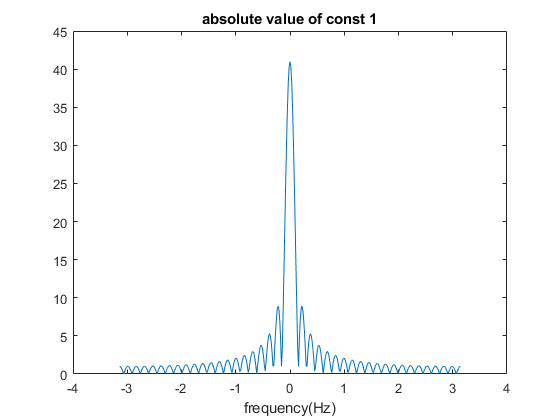


n = 0:40;
x2(n+1) = 1;
y2 = DTFT(x2,n);
plot(s,abs(y2))
title("absolute value of const 1")
xlabel("frequency(Hz)")

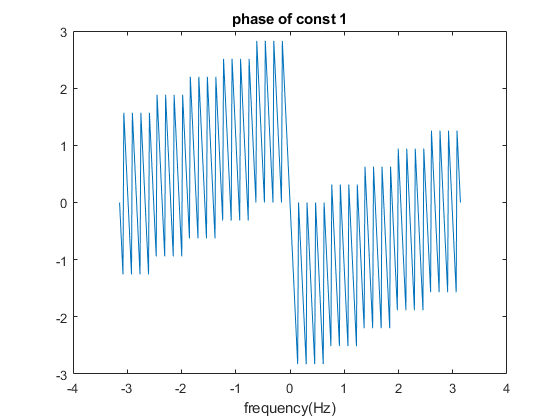


plot(s,angle(y2))
title("phase of const 1")
xlabel("frequency(Hz)")

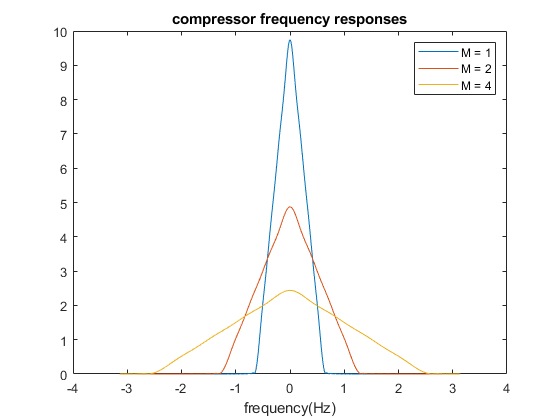

n = -3.9:0.1:4;
x3 = sinc(n).*sinc(n);
y3 = DTFT(x3,n*10);
x4 = compressor(x3,2);
n = -3.9:0.2:4;
y4 = DTFT(x4,n*5);
x5 = compressor(x3,4);
n = -3.9:0.4:4;
y5 = DTFT(x5,n*2.5);
plot(s,abs(y3))
title("compressor frequency responses")
xlabel("frequency(Hz)")
hold on
plot(s,abs(y4))
plot(s,abs(y5))
legend("M = 1","M = 2", "M = 4");
hold off

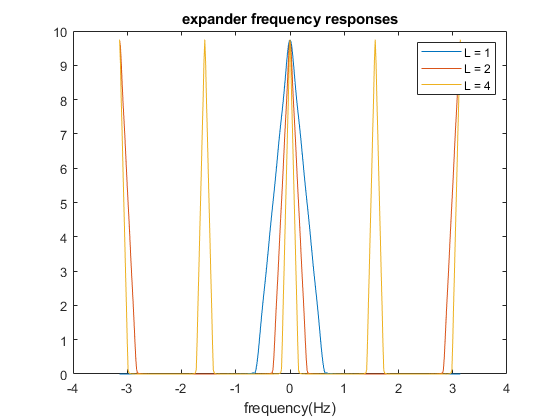

n = -3.9:0.1:4;
x6 = sinc(n).*sinc(n);
y6 = DTFT(x6,n*10); 
x7 = expander(x6,2);
y7 = DTFT(x7,(-3.95:0.05:4)*20);
x8 = expander(x6,4);
y8 = DTFT(x8,(-3.975:0.025:4)*40);
plot(s,abs(y6))
title("expander frequency responses")
xlabel("frequency(Hz)")
legend();
hold on
plot(s,abs(y7))
plot(s,abs(y8))
legend("L = 1","L = 2", "L = 4");
hold off

fs = 20

fs = 20

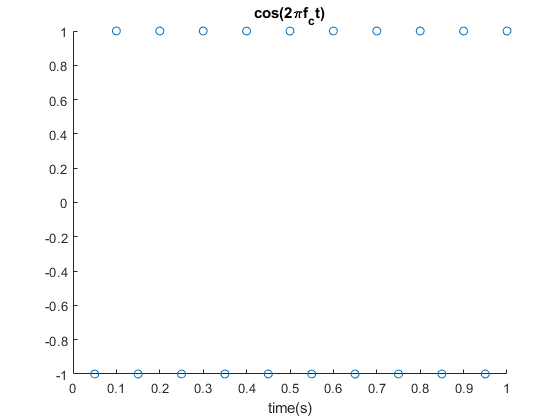

t = 1/fs:1/fs:1;

s = -pi:pi/200:pi;
sd = cos(2*pi * 10 * t);
scatter(t,sd);
title("cos(2\pif_{c}t)")
xlabel("time(s)")

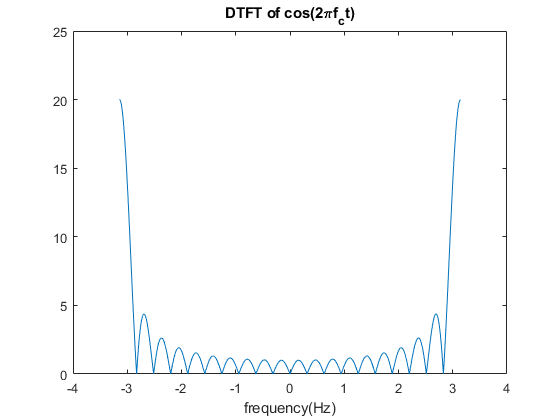

Fsd = DTFT(sd,t*fs);
plot(s,abs(Fsd));
title("DTFT of cos(2\pif_{c}t)")
xlabel("frequency(Hz)")

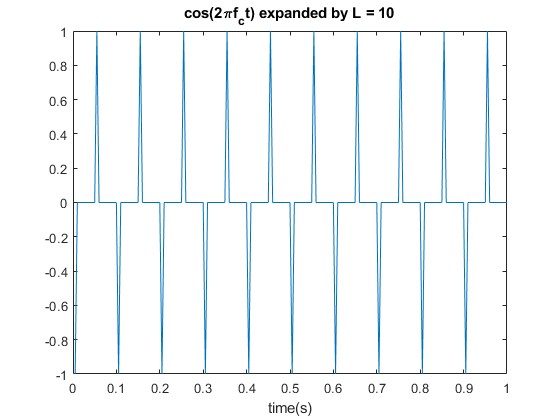



L = 10;
t2 = 1/fs/L:1/L/fs:1;
sdL = expander(sd,L);
plot(t2,sdL);
title("cos(2\pif_{c}t) expanded by L = 10")
xlabel("time(s)")

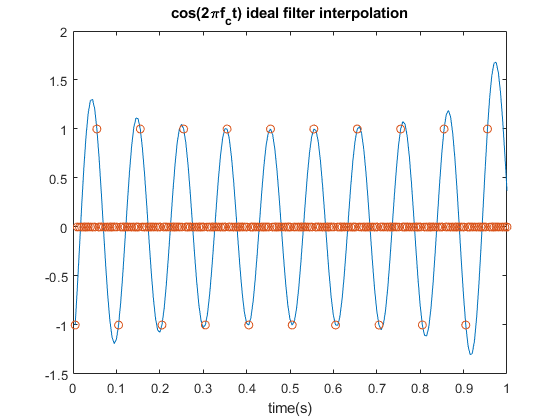


x8 = Interpolate(sdL,1,t2,fs,L);
x9 = Interpolate(sdL,2,t2,fs,L);
x10 = Interpolate(sdL,3,t2,fs,L);

plot(t2,x8)
title("cos(2\pif_{c}t) ideal filter interpolation")
xlabel("time(s)")
hold on
scatter(t2,sdL)
hold off

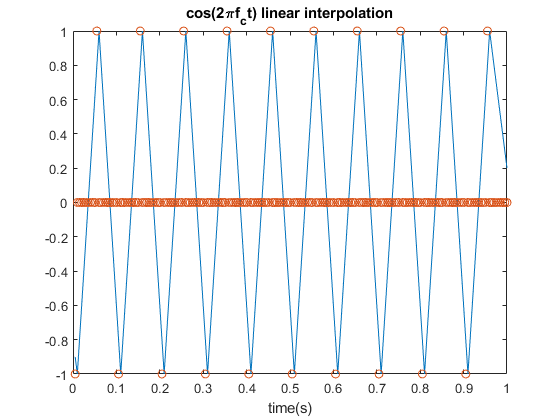


plot(t2,x9)
title("cos(2\pif_{c}t) linear interpolation")
xlabel("time(s)")
hold on
scatter(t2,sdL)
hold off

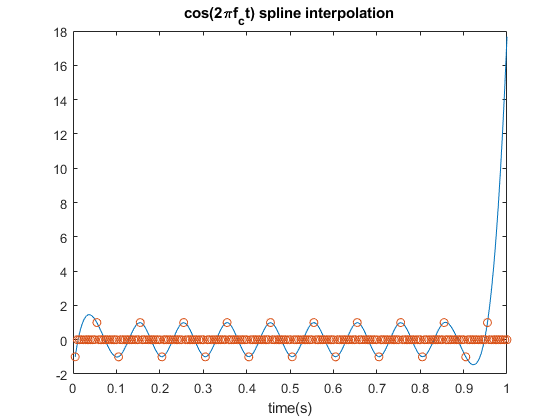


plot(t2,x10)
title("cos(2\pif_{c}t) spline interpolation")
xlabel("time(s)")
hold on
scatter(t2,sdL)
hold off


x_ref = cos(2*pi* 10*t2);

x_ref =     0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090    0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090    0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000


sprintf("mse for ideal interpolation is %f", immse(x_ref,x8))

ans = "mse for ideal interpolation is 2.037515"

sprintf("mse for linear interpolation is %f", immse(x_ref,x9))

ans = "mse for linear interpolation is 1.485905"

sprintf("mse for spline interpolation is %f", immse(x_ref,x10))

ans = "mse for spline interpolation is 6.000488"

fs = 200

fs = 200

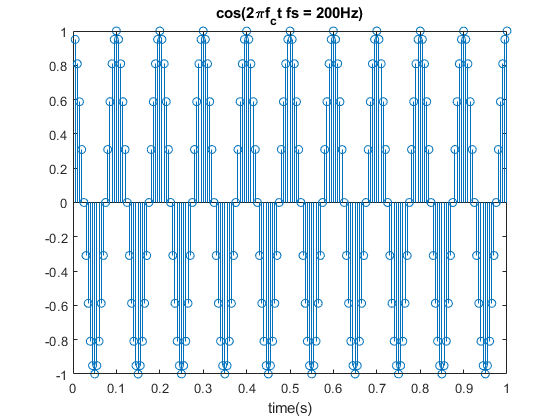

t = 1/fs:1/fs:1;

s = -pi:pi/200:pi;
sd = cos(2*pi * 10 * t);
stem(t,sd);
title("cos(2\pif_{c}t fs = 200Hz)")
xlabel("time(s)")

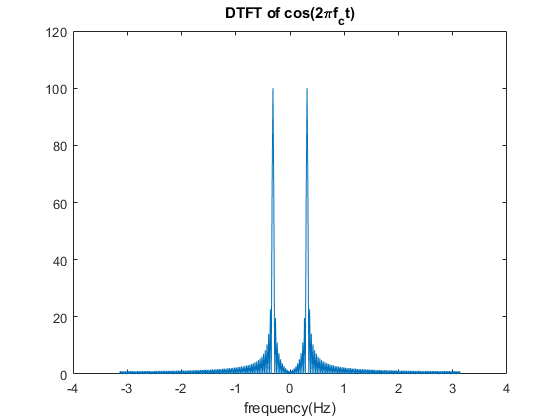

Fsd = DTFT(sd,t*fs);
plot(s,abs(Fsd));
title("DTFT of cos(2\pif_{c}t)")
xlabel("frequency(Hz)")

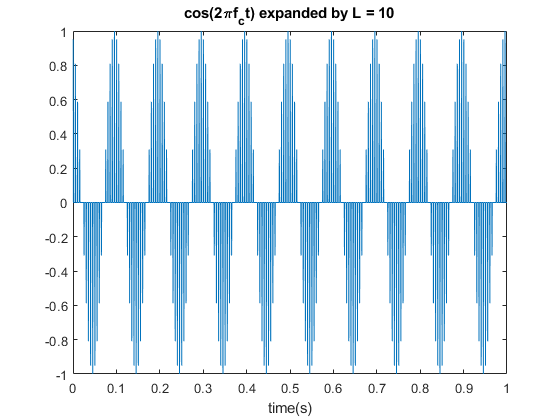



L = 10;
t2 = 1/fs/L:1/L/fs:1;
sdL = expander(sd,L);
plot(t2,sdL);
title("cos(2\pif_{c}t) expanded by L = 10")
xlabel("time(s)")

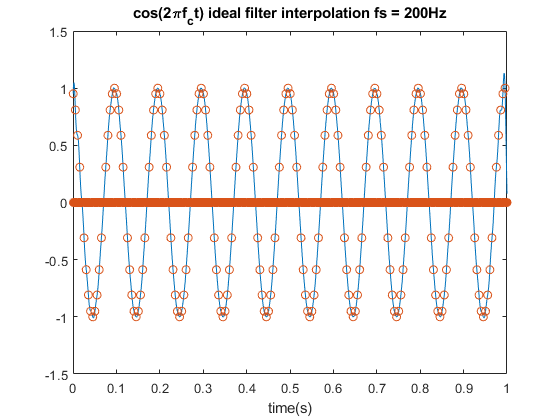


x8 = Interpolate(sdL,1,t2,fs,L);
x9 = Interpolate(sdL,2,t2,fs,L);
x10 = Interpolate(sdL,3,t2,fs,L);

plot(t2,x8)
title("cos(2\pif_{c}t) ideal filter interpolation fs = 200Hz")
xlabel("time(s)")
hold on
scatter(t2,sdL)
hold off

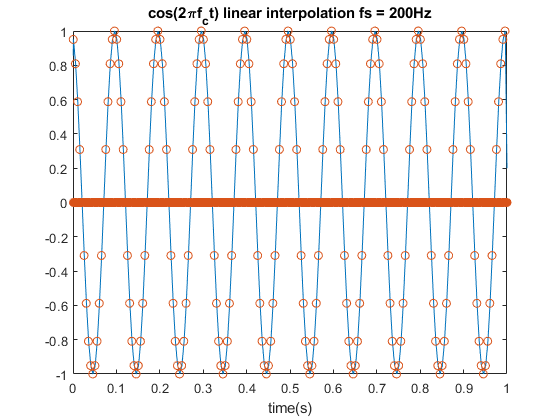


plot(t2,x9)
title("cos(2\pif_{c}t) linear interpolation fs = 200Hz")
xlabel("time(s)")
hold on
scatter(t2,sdL)
hold off

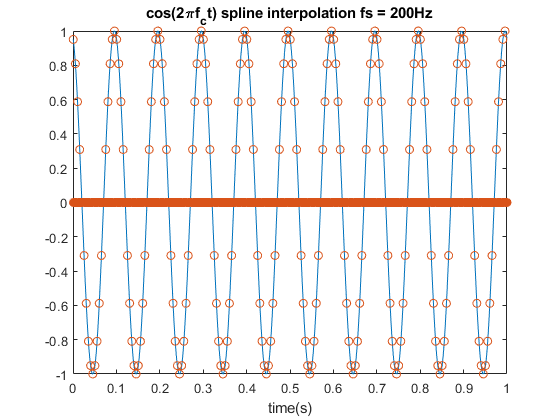


plot(t2,x10)
title("cos(2\pif_{c}t) spline interpolation fs = 200Hz")
xlabel("time(s)")
hold on
scatter(t2,sdL)
hold off


x_ref = cos(2*pi* 10*t2);
sprintf("mse for ideal interpolation is %f", immse(x_ref,x8))

ans = "mse for ideal interpolation is 0.041334"

sprintf("mse for linear interpolation is %f", immse(x_ref,x9))

ans = "mse for linear interpolation is 0.032213"

sprintf("mse for spline interpolation is %f", immse(x_ref,x10))

ans = "mse for spline interpolation is 0.039706"

Part 2

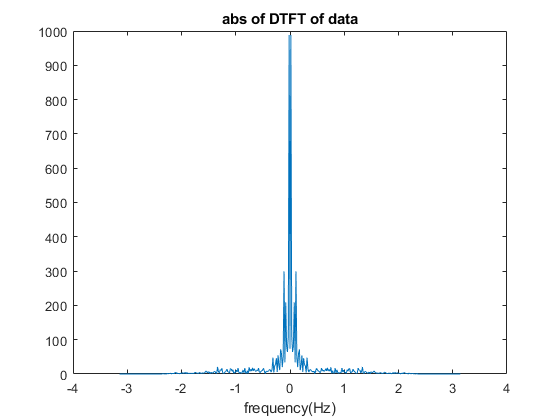

[data,Fs] = audioread("sound.mp3");
data = data(:,1);
data = transpose(data);
t = 0:1/Fs:(length(data)-1)/Fs;

Fdata = DTFT(data,t*Fs);
plot(s,abs(Fdata));
title("abs of DTFT of data")
xlabel("frequency(Hz)")

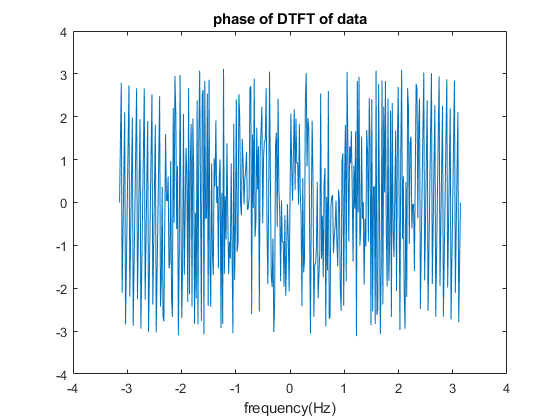


plot(s,angle(Fdata));
title("phase of DTFT of data")
xlabel("frequency(Hz)")

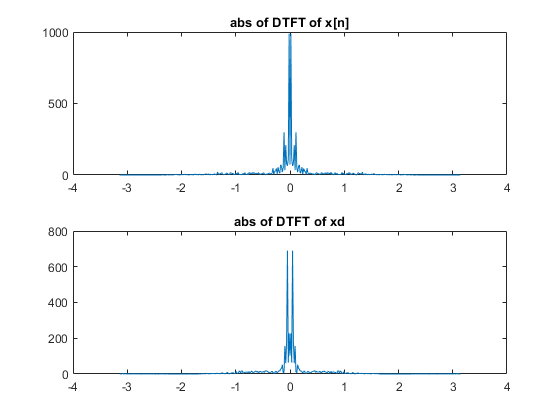

[L,M] = rat(61150/Fs);
xe = expander(data,L);
fs = L*Fs;

subplot(2,1,1)
plot(s,abs(Fdata))
title("abs of DTFT of x[n]")

%subplot(4,1,2)
%plot(s,abs(DTFT(xe,1:length(xe))))
%title("abs of DTFT of xe")

%subplot(4,1,3)
ye = Interpolate(xe,2,t,Fs,L);
%plot(s,abs(DTFT(ye,1:lenght(ye))))
%title("abs of DTFT of ye")

subplot(2,1,2)
%Fs = Fs/M;
%t = 0:1/Fs:(length(data)-1)/Fs;
xd = compressor(ye,M);
plot(s,abs(DTFT(xd,1:length(xd))))
title("abs of DTFT of xd")



sound(xd,66150)
sound(data,44100)

Part 3

n = 0:2499;
x = zeros(1,length(n));
x(1:26) = 14;
X = DTFT(x,n);
sprintf("3dB bandwidth for s0 is %f", BW3db(X))

ans = "3dB bandwidth for s0 is 0.203694"

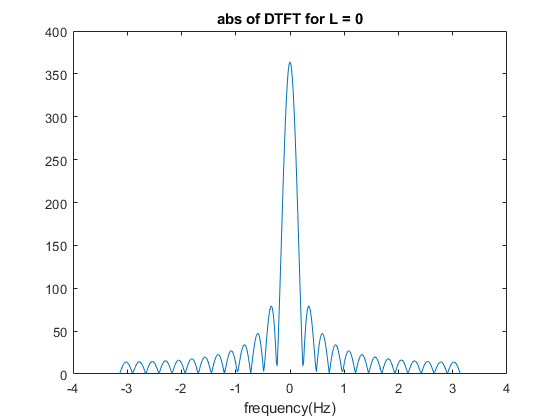

plot(s,abs(X))
title("abs of DTFT for L = 0")
xlabel("frequency(Hz)")

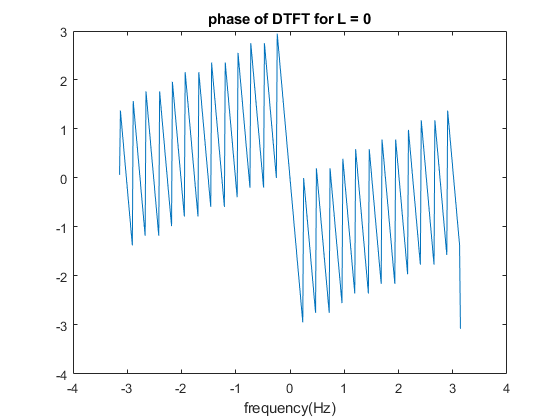

plot(s,angle(X))
title("phase of DTFT for L = 0")
xlabel("frequency(Hz)")


s2 = [x,x,x];
Fs2 = DTFT(s2,0:7499);
sprintf("3dB bandwidth for s2 is %f", BW3db(Fs2))

ans = "3dB bandwidth for s2 is 0.047006"

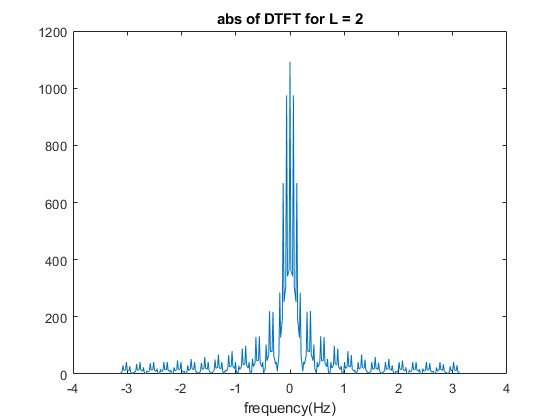

plot(s,abs(Fs2))
title("abs of DTFT for L = 2")
xlabel("frequency(Hz)")

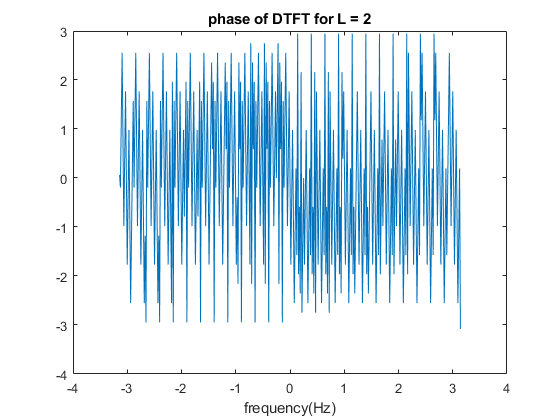

plot(s,angle(Fs2))
title("phase of DTFT for L = 2")
xlabel("frequency(Hz)")


s5 = [s2,s2];
Fs5 = DTFT(s5,0:14999);
sprintf("3dB bandwidth for s5 is %f", BW3db(Fs5))

ans = "3dB bandwidth for s5 is 0.047006"

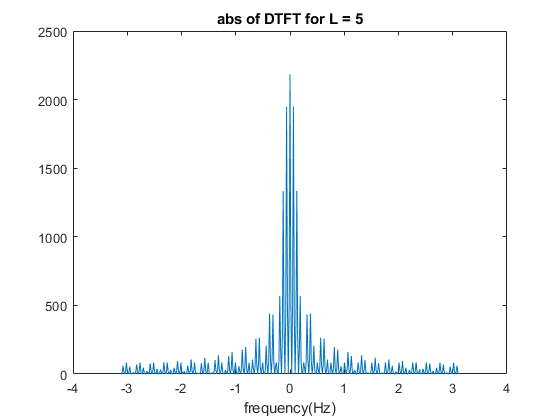

plot(s,abs(Fs5))
title("abs of DTFT for L = 5")
xlabel("frequency(Hz)")

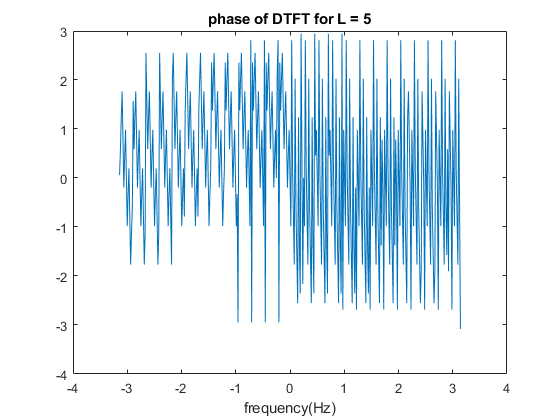

plot(s,angle(Fs5))
title("phase of DTFT for L = 5")
xlabel("frequency(Hz)")

Part 4

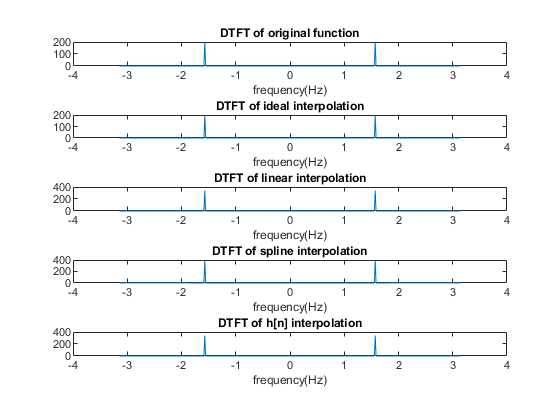

%fs = 4fc
fs = 400;
t = 0:1/fs :1-1/fs;
s = -pi:pi/200:pi;
fc = 100;
xd = cos(2*pi *fc *t);

subplot(5,1,1)
plot(s,abs(DTFT(xd,t*fs)))
title("DTFT of original function")
xlabel("frequency(Hz)")

t2 = 0:1/2/fs :1-1/2/fs;
xe = expander(xd,2);
%plot(s,abs(DTFT(xe,t*2*fs)))

subplot(5,1,2)
y1 = Interpolate(xe,1,t2*2*fs,2,2);
plot(s,abs(DTFT(y1,t2*fs)))
title("DTFT of ideal interpolation")
xlabel("frequency(Hz)")

subplot(5,1,3)
y2 = Interpolate(xe,2,t2*2*fs,2,2);
plot(s,abs(DTFT(y2,t2*fs)))
title("DTFT of linear interpolation")
xlabel("frequency(Hz)")

subplot(5,1,4)
y3 = Interpolate(xe,3,t2*2*fs,2,2);
plot(s,abs(DTFT(y3,t2*fs)))
title("DTFT of spline interpolation")
xlabel("frequency(Hz)")

subplot(5,1,5)
b = [1/2 1 1/2];
a = [1];
y4 = filter(b,a,xe);
plot(s,abs(DTFT(y4,t2*fs)))
title("DTFT of h[n] interpolation")
xlabel("frequency(Hz)")

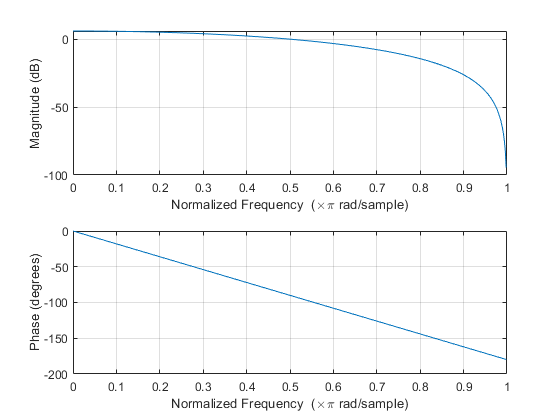

freqz(b,a);

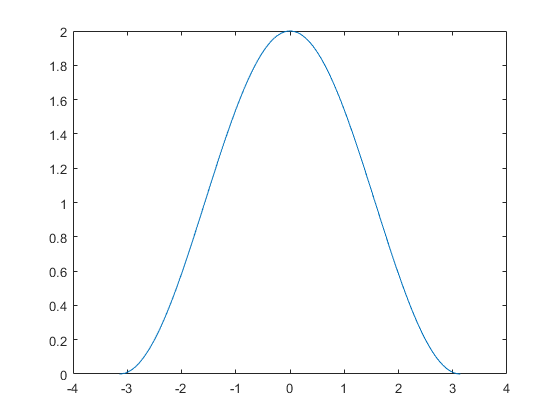

n = t2*fs*2;
h = zeros(1,length(n));
h(1:3) = [0.5 1 0.5];
plot(s,abs(DTFT(h,n)))

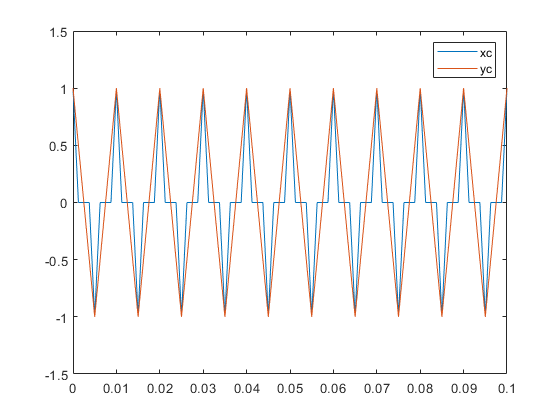

plot(t2,y1)
hold on
plot(t,xd)
legend("xc","yc")
xlim([0 0.1])
hold off

Part 5

num = [1 2 3 4];
den = [4 3 2 1];
z = tf('z'); 
H = tf(( 1+ 2*z^(-1) +3* z^(-2) + 4* z^(-3))/( 4+ 3*z^(-1) +2* z^(-2) + 1* z^(-3)), 'Variable','z^-1')


H =
 
  z^12 + 2 z^11 + 3 z^10 + 4 z^9
  ------------------------------
  4 z^12 + 3 z^11 + 2 z^10 + z^9
 
Sample time: unspecified
Discrete-time transfer function.



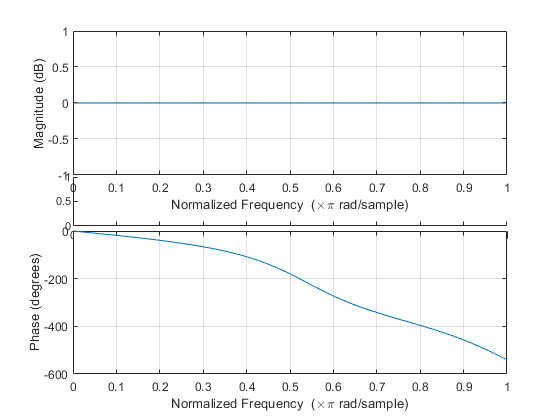

freqz(num,den)

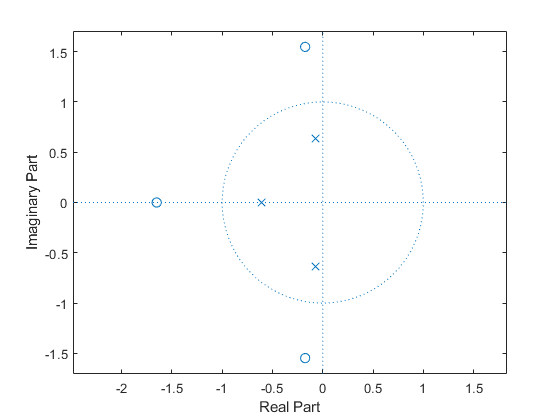

zplane(num,den)

[data,fs] =audioread("speech.wav");
y = filter(num,den,data);
audiowrite("output1.wav",y,fs)

bout = num;
aout = den;
N = 15

N = 15

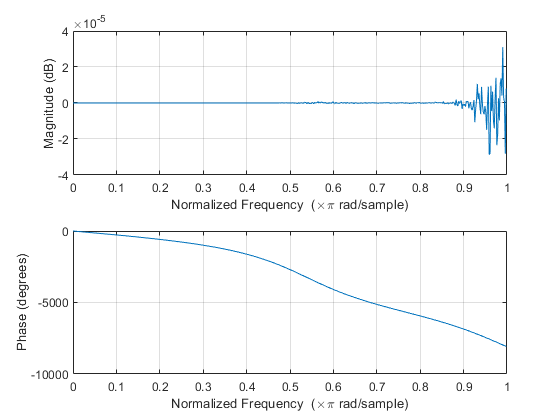

for i = 1:N-1
    bout = conv(num,bout);
    aout = conv(den,aout);
end
freqz(bout,aout)

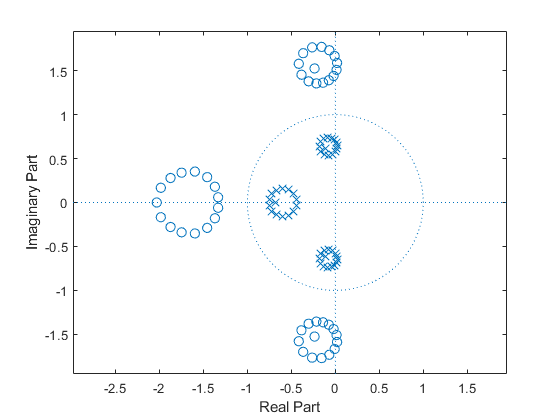

zplane(bout,aout)

y = filter(bout,aout,data);
audiowrite("output2.wav",y,fs)

bout = num;
aout = den;
N = 50

N = 50

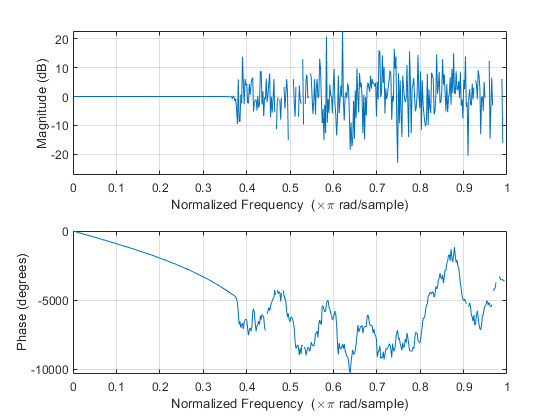

for i = 1:N-1
    bout = conv(num,bout);
    aout = conv(den,aout);
end
freqz(bout,aout)

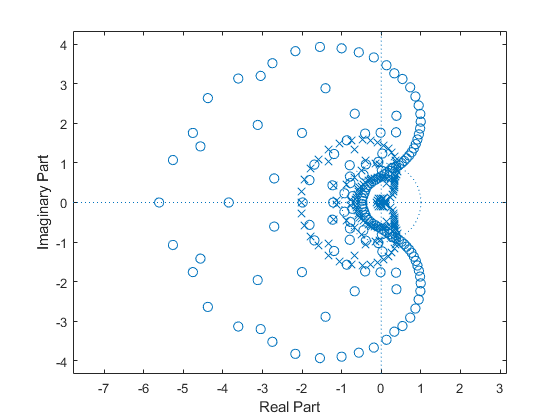

zplane(bout,aout)

y = filter(bout,aout,data);
sound(y,fs)


Part 6

bn = [0.45 0.4 -1];
an = [1 -0.4 -0.45];

bx = [6 -4];
ax = [2 -3 1];

Y = [0 3];
X = [2 2];

% this give numinators of zero input response 
ic = filtic(bn,an,Y,X); 

%this part forms Y in Z domain
by = conv(bn,bx) + conv(ic,ax);
ay = conv(an,ax);

[r,p,k] = residuez(by,ay)

r =    -2.0000
    2.1116
    1.7188
   -0.3304


p =     1.0000
    0.9000
    0.5000
   -0.5000



k =

     []



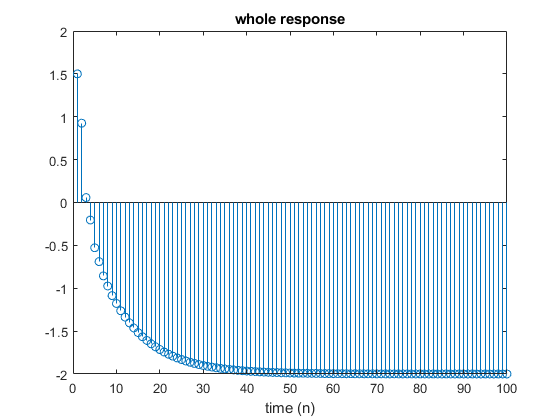

n = 0:99;

% using remaindes and poles we form y in time domain by exponential terms
y = r(1)* p(1).^n + r(2)*p(2).^n + r(3)*p(3).^n + r(4)*p(4).^n;
stem(y)
title("whole response")
xlabel("time (n)")

%this part plots the zero input response of y
[r,p,k] = residuez(ic,an)

r =    -1.3321
    1.4821


p =     0.9000
   -0.5000



k =

     []



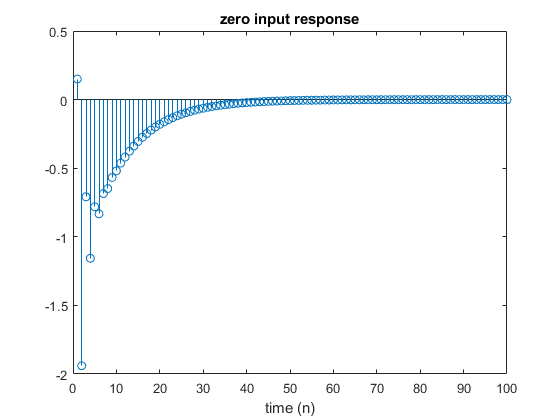

yzr =  r(1)* p(1).^n + r(2)*p(2).^n;
stem(yzr)
title("zero input response")
xlabel("time (n)")


%this part plots the zero state response
b =conv(bn,bx);
a = conv(an,ax);
[r,p,k] = residuez(b,a)

r =    -2.0000
    3.4437
    1.7188
   -1.8125


p =     1.0000
    0.9000
    0.5000
   -0.5000



k =

     []



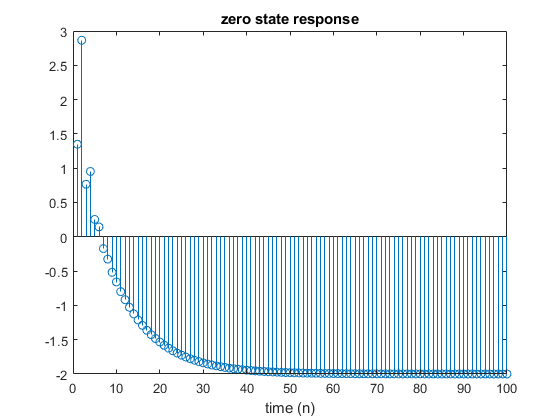

yzs = r(1)* p(1).^n + r(2)*p(2).^n + r(3)*p(3).^n + r(4)*p(4).^n;
stem(yzs)
title("zero state response")
xlabel("time (n)")

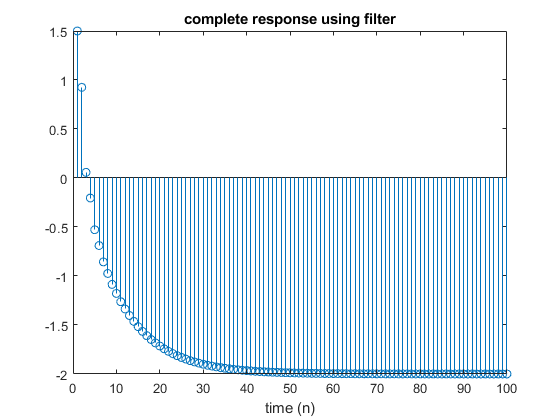

% complete response using filtic and filter
Y = [0 3];
X = [2 2];
x = (1/2).^n + 2;
xic = filtic(bn,an,Y,X);
yzi = filter(bn,an,x,xic);
stem(yzi)
title("complete response using filter")
xlabel("time (n)")

function y = compressor(x,M)
y = x(1:M:length(x));
end

function X = DTFT(x,n)
k = -200:200;
X = x*(exp(-j*pi/200)).^(n'*k);
end


function y = expander(x,L)
N = length(x)*L;
y = zeros(1,N);
y(1:L:N) = x;
end

function y = Interpolate(x,mode,n,fs,L)
switch mode
    case 1
        [Ts,T] =ndgrid(n,n(1:L:length(n)));
        y = sinc((Ts - T)*fs)*transpose(x(1:L:length(n)));
        y = transpose(y);
    case 2
        h = zeros(1,2*L -1);
        for t = -L:L
            h(t+L+1) = 1- abs(t)/L;
        end
        y = conv(x,h); 
        y = y(L:length(y)-L-1);
    case 3
        y = spline(n(1:L:length(n)),x(1:L:length(n)),n);
        
end

end

function y = BW3db(x)
N = length(x);
M = max(abs(x));
counter = 0;
for n = 1:N
    if abs(x(n)) > sqrt(2)/2*M
        counter = counter +1;
    end
end
y = counter/n *2*pi;
end